# Sin Function Test

## Clear Workspace

close all; clearvars; clc;

## Vars

N = 500e3; % sets the length of buffer for preloading
sample_HZ = 1e6; % frequency HZ
A = 0.5; % amplitude p-pk V
duration = 0.5;
f1 = 75e3; % lowest frequency component Hz
f2 = 100e3; % mid frequency component Hz
f3 = 125e3; % highest frequency component Hz


## Wave Gen Function

%new
periods = 1/eval(gcd(sym([f1 f2 f3]))); % calculates the length of the period for a periodic
timeStep = 1/sample_HZ; % period of the sampling frequency
t = (0:timeStep:periods-timeStep)'; % calculates the time vector from the period

y = A*sin(2*pi*f1*t) + A*sin(2*pi*f2*t) + A*sin(2*pi*f3*t); % calculates the signal along the time vector
numCycles = ceil(N/length(y)); % calculate the number of cycles to make a full buffer for preloading
sine = repmat(y, numCycles, 1); % extends the data vector to match or execed the buffer length

%old
numSamplesPerCycle = floor(sample_HZ/f1);
Told = 1/f1;
timestepold = Told/numSamplesPerCycle;
told = (0 : timestepold : Told-timestepold)';

yold = A*sin(2*pi*f1*told) + A*sin(2*pi*f2*told) + A*sin(2*pi*f3*told);

numCyclesold = round(f1*duration);
sineold = repmat(y,numCyclesold,1);

## Plot Waves

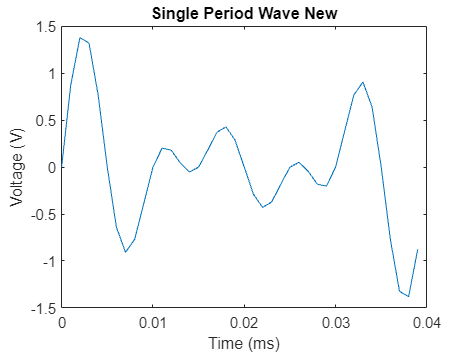

figure
plot(t*1e3, y)
ylabel('Voltage (V)')
xlabel('Time (ms)')
title('Single Period Wave New')

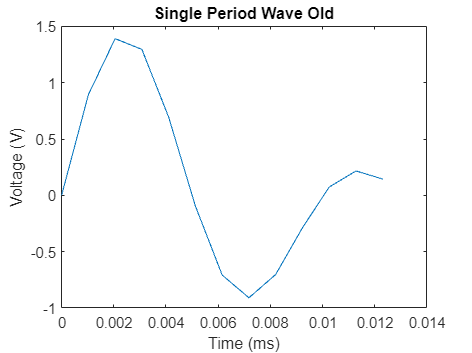


figure
plot(told*1e3, yold)
ylabel('Voltage (V)')
xlabel('Time (ms)')
title('Single Period Wave Old')

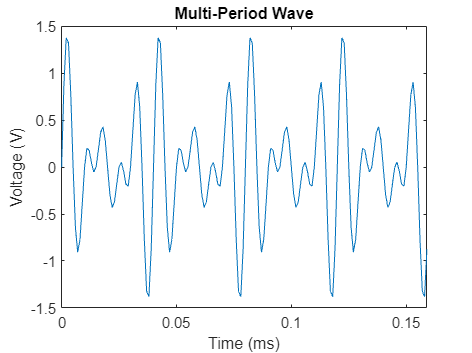


t1 = (0:timeStep:periods*4-timeStep)';
points = floor((periods/timeStep)*4);
figure
plot(t1*1e3, sine(1:points))
ylabel('Voltage (V)')
xlabel('Time (ms)')
title('Multi-Period Wave')

## Plot FFT

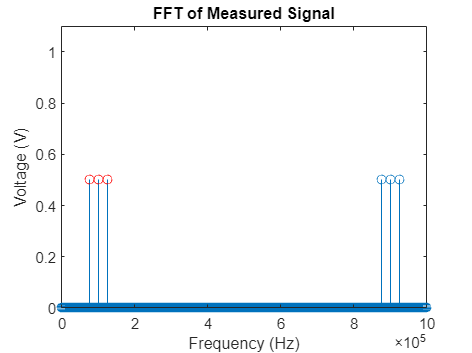

FFT_signal = fft(sine, N);
f_HZ1 = ((0:N-1)*sample_HZ)/N;
figure;
stem(f_HZ1, abs(FFT_signal)/N*2)
title('FFT of Measured Signal')
ylabel('Voltage (V)')
xlabel('Frequency (Hz)')
hold on
plot(f1, 0.5, 'r o', f2, 0.5, 'r o', f3, 0.5, 'r o')
ylim([0 1.1])